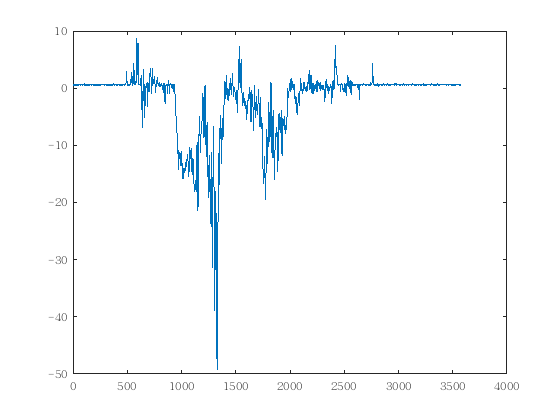

clear all
data=textread('AHRS/data/memsData1.txt');
dT=0.005;
plot(data(:,3));

%角速度去零飘处理
dT=0.005;
staticNum=400;static=399;
wx=data(staticNum:end,1)-mean(data(staticNum-static:staticNum,1));
wy=data(staticNum:end,2)-mean(data(staticNum-static:staticNum,2));
wz=(data(staticNum:end,3)-mean(data(staticNum-static:staticNum,3)));

%加速度计归一化处理
axRaw=data(staticNum:end,4);
ayRaw=data(staticNum:end,5);
azRaw=data(staticNum:end,6);
normAcc=sqrt(sum(data(staticNum:end,4:6).^2,2));
ax=axRaw./normAcc;
ay=ayRaw./normAcc;
az=azRaw./normAcc;

%积分量初始化
initEuler=[atan2d(-ay(1),-az(1)) asind(ax(1)) zeros(length(ax(1)),1)];%欧拉角初始化
initQuaternion=euler2quat_self(initEuler);%四元数初始化
quaternion=initQuaternion;
qUKF=initQuaternion';

n=4;      %number of state
r=0.1;    %std of process 
q=0.1;    %std of measurement
R=r^2*eye(n); % covariance of process
Q=q^2;        % covariance of measurement 
f=@(qUKF,w,T) figureA_k(w,dT)*qUKF; % nonlinear state equations
h=@(qUKF,w,T) -[2*qUKF(2)*qUKF(4)-2*qUKF(1)*qUKF(3);2*qUKF(1)*qUKF(2)+2*qUKF(3)*qUKF(4);qUKF(1)^2-qUKF(2)^2-qUKF(3)^2+qUKF(4)^2];                               % measurement equation
P = eye(n);                               % initial state covraiance 初始估计变量的协方差
N=length(wx);                                     % total dynamic steps
xV = zeros(n,N);            %无迹卡尔曼滤波估计值（V表示向量）        % allocate memory
zV = zeros(3,N);            %测量值为一维
for i=1:N
    
    %纯陀螺仪的积分
    quaternion=quatInt(quaternion,[wx(i);wy(i);wz(i)],dT);
    GyroAngle(i,1:3)=quat2euler_self(quaternion);
    
    z=[ax(i);ay(i);az(i)];
    [qUKF, P] = ukf(f,qUKF,P,h,z,R,Q,[wx(i);wy(i);wz(i)],dT);            % ekf 
    %航向角不参与融合
    eulerT=quat2euler_self(qUKF);
    eulerT(3)=GyroAngle(i,3);
    qUKF=euler2quat_self(eulerT)';
    normX=sqrt(sum(qUKF.^2));
    qUKF=qUKF/normX;
    
    EKFAngle(i,1:3)=quat2euler_self(qUKF);

end

%纯加速度计算出的角度
AccAngle=[atan2d(-ay,-az) asind(ax) zeros(length(ax),1)];

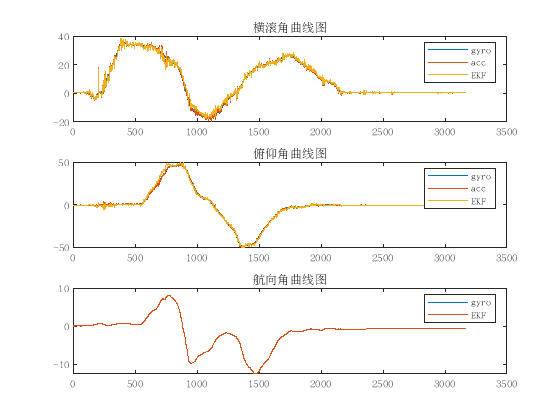

%画图
figure
subplot(311);
plot(GyroAngle(:,1));hold on;
plot(AccAngle(:,1));hold on;
plot(EKFAngle(:,1));
title('横滚角曲线图')
legend('gyro','acc','EKF');
subplot(312);
plot(GyroAngle(:,2));hold on;
plot(AccAngle(:,2));hold on;
plot(EKFAngle(:,2));
title('俯仰角曲线图')
legend('gyro','acc','EKF');
subplot(313);
plot(GyroAngle(:,3));hold on;
plot(EKFAngle(:,3));
title('航向角曲线图')
legend('gyro','EKF');

function [A_k] = figureA_k(palstance,dT)
    A_k=[ 0 -palstance(1) -palstance(2) -palstance(3) ;
          palstance(1) 0 palstance(3) -palstance(2) ;
          palstance(2) -palstance(3) 0 palstance(1) ;
          palstance(3) palstance(2) -palstance(1) 0 ; ];
    A_k=eye(4)+A_k*0.5*dT;
end